# Stability Criteria

Rover shall be designed to safely accommodate a 20° slope in any direction at a speed of at least 1 m/sec and including the ability to start and stop.

## Parameters

Slope $\theta =20$ degrees

Mass $m = 670$ kg

Gravity $g = 1.62 \frac{m}{s^2{$ 

r = wheel radius (m)

h = height (m) between the wheel axes and CoM

l = length (m) between the front and rear axles

a = length (m) between the front axle and CoM

ax = longitudinal acceleration $\frac{m}{s^2}$

## Longitudinal Dynamic Stability


$$N_1 = mg\bigg(\bigg(1-\frac{a}{l}\bigg)cos\theta-\bigg(\frac{h}{l}+\frac{r}{l}\bigg)sin\theta-\frac{a_x}{g}\bigg)$$



$$N_2 = mg\bigg(\frac{a}{l}cos\theta+\bigg(\frac{h}{l}+\frac{r}{l}\bigg)sin\theta+\frac{a_x}{g}\bigg)$$



$$T_1 = \frac{N_1}{N_1+N_2}(mgsin\theta+ma_x)$$



$$T_2 = \frac{N_2}{N_1+N_2}(mgsin\theta+ma_x)$$


clear vars
clc
close all

theta = deg2rad(20); % Slope (rad)
m = 670; %kg, total (max) rover mass (1 crew)
g = 1.62; %m/s^2, accel due to gravity on the Moon

syms h l ax a r slope

N1 = m*g*((1-(a/l))*cos(theta)-((h/l)+(r/l))*sin(theta)-(ax/g))/2; % Normal force (N) on each of the front two wheels
N2 = m*g*((a/l)*cos(theta)+((h/l)+(r/l))*sin(theta)-(ax/g))/2; % Normal force (N) on each of the rear two wheels
T_RR = (N2/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the rear right wheel
T_RL = (N2/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the rear left wheel
T_FR = (N1/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the front right wheel
T_FL = (N1/(N1+N2))*m*g*sin(theta)+m*ax; % Torque (Nm) applied by the front left wheel

h_ =0.6;
l_ =2.6;
r_ =0.3;
a_ =1.3;
ax_=0.5;


N1_ = double(subs(N1,[h l ax a r],[h_ l_ ax_ a_ r_]))

N1_ = 23.2345

N2_ = double(subs(N2,[h l ax a r],[h_ l_ ax_ a_ r_]))

N2_ = 151.7367

T_F = double(subs(T_FR,[h l ax a r],[h_ l_ ax_ a_ r_]))

T_F = 384.2956

T_R = double(subs(T_RR,[h l ax a r],[h_ l_ ax_ a_ r_]))

T_R = 656.9331

### Graphs

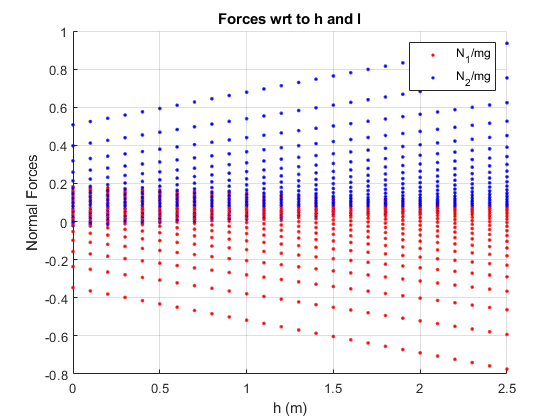

% 3D plot (h vs l vs normal forces)
slope1 = 20;
N1_list = [];
N2_list = [];
h_list = [];
l_list = [];

for h_trial = 0:0.1:2.5
    for l_trial = 1:0.2:5
          N1 = m*g*((1-(a_/l_trial))*cosd(slope1)-((h_trial/l_trial)+(r_/l_trial))*sind(slope1)-(ax_/g))/2;
          N2 = m*g*((a_/l_trial)*cosd(slope1)+((h_trial/l_trial)+(r_/l_trial))*sind(slope1)-(ax_/g))/2;  
          N1_norm = N1/(m*g);
          N2_norm = N2/(m*g);
          N1_list = [N1_list,N1_norm];
          N2_list = [N2_list,N2_norm];
          h_list=[h_list,h_trial];
          l_list=[l_list,l_trial];
    end
end
figure
hold on
plot3(h_list,l_list,N1_list,'.r')
plot3(h_list,l_list,N2_list,'.b')
xlabel('h (m)')
ylabel('l (m)')
zlabel('Normal Forces')
legend('N_1/mg','N_2/mg')
title('Forces wrt to h and l')
%[x,y] = meshgrid(0:0.1:2.5,1:0.1:6);
%z=0.*x+0.*y;
%surf(x,y,z,'FaceAlpha',0.1)
hold off
grid on
view (0,360)

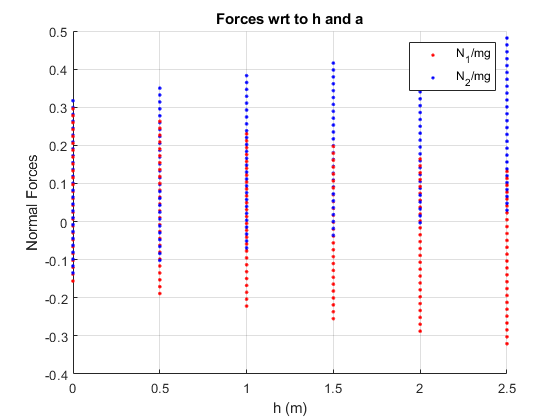


clear N1_list N2_list h_list l_list

% 3D plot (h vs a vs normal forces)
slope1 = 20;
N1_list = [];
N2_list = [];
h_list = [];
a_list = [];

for h_trial = 0:0.5:2.5
    for a_trial = 0:0.1:2.5
          N1 = m*g*((1-(a_trial/l_))*cosd(slope1)-((h_trial/l_)+(r_/l_))*sind(slope1)-(ax_/g))/2;
          N2 = m*g*((a_trial/l_)*cosd(slope1)+((h_trial/l_)+(r_/l_))*sind(slope1)-(ax_/g))/2;  
          N1_norm = N1/(m*g);
          N2_norm = N2/(m*g);
          N1_list = [N1_list,N1_norm];
          N2_list = [N2_list,N2_norm];
          h_list=[h_list,h_trial];
          a_list=[a_list,a_trial];
    end
end

figure
hold on
plot3(h_list,a_list,N1_list,'.r')
plot3(h_list,a_list,N2_list,'.b')
xlabel('h (m)')
ylabel('a (m)')
zlabel('Normal Forces')
legend('N_1/mg','N_2/mg')
title('Forces wrt to h and a')
%[x,y] = meshgrid(0:0.1:2.5,0:0.1:2.5);
%z=0.*x+0.*y;
%surf(x,y,z,'FaceAlpha',0.1)
hold off
grid on
view (0,360)

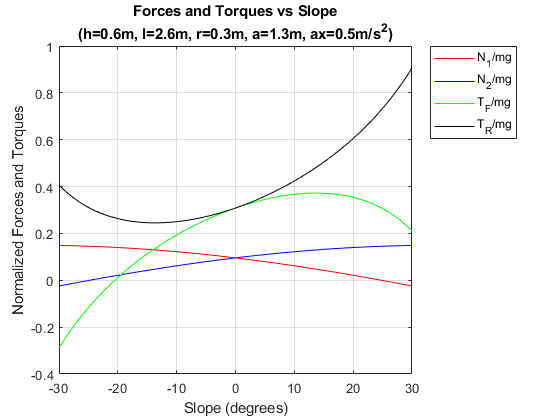

clear N1_list N2_list h_list a_list


% 2D plot
slope = -30:0.05:30;
N1_list = zeros(1,length(slope));
N2_list = zeros(1,length(slope));
T_R_list = zeros(1,length(slope));
T_F_list = zeros(1,length(slope));

for i = 1: length(slope)
    N1_list(i) = m*g*((1-(a_/l_))*cosd(slope(i))-((h_/l_)+(r_/l_))*sind(slope(i))-(ax_/g))/2;
    N2_list(i) = m*g*((a_/l_)*cosd(slope(i))+((h_/l_)+(r_/l_))*sind(slope(i))-(ax_/g))/2;
    T_F_list(i) = (N1_list(i)/(N1_list(i)+N2_list(i)))*m*g*sind(slope(i))+m*ax_;
    T_R_list(i) = (N2_list(i)/(N1_list(i)+N2_list(i)))*m*g*sind(slope(i))+m*ax_; 
end
plot(slope,N1_list./(m*g),'red')
hold on
plot(slope,N2_list./(m*g),'blue')
hold on
plot(slope,T_F_list./(m*g),'green')
hold on
plot(slope, T_R_list./(m*g), 'black')
hold off
legend('N_1/mg','N_2/mg','T_{F}/mg','T_{R}/mg')
xlabel('Slope (degrees)')
ylabel("Normalized Forces and Torques")
graph_title=strcat('(h=',num2str(h_),'m, l=',num2str(l_),'m, r=',num2str(r_),'m, a=',num2str(a_),'m, ax=',num2str(ax_),'m/s^2)');
title({'Forces and Torques vs Slope',graph_title})

grid on

### Overturn Limits

- For dynamic case:

#### 
$$(1-\frac{a}{l})cos{\theta_{limit}} - (\frac{h}{l}+\frac{r}{l})sin{\theta_{limit}} = \frac{a_x}{g}
$$


syms theta_l_d

eqn = ((1-(a_/l_))*cos(theta_l_d) - ((h_+r_/l_)*sin(theta_l_d)));
Theta_limit_d = rad2deg(double(solve(eqn,theta_l_d)))

Theta_limit_d =  -145.0493
   34.9507


- For static case: 


$$tan{\theta_{limit}} = \frac{l-a}{h+r}$$


syms theta_l_s
Theta_limit_s = rad2deg(atan((l_-a_)/(h_+r_)))

Theta_limit_s = 55.3048

#### Limiting acceleration on flat ground : $a_{x,limit} = g(1-\frac{a}{l})$

a_x_limit = g*(1-(a_/l_))

a_x_limit = 0.8100

### Limits on slope

- Acceleration :  

 
$$\frac{dv}{dt}\Bigr|_{lim} = g[(\frac{l-a}{r+h})cos{\theta} - sin{\theta}]$$


- Deceleration


$$\frac{dv}{dt}\Bigr|_{lim} =- g[(\frac{a}{r+h})cos{\theta} + sin{\theta}]$$


theta = 0:1:60;
dvdt_a = g*(((l_-a_)*cosd(theta)/(r_+h_)) - sind(theta));
Limited_Acceleration = [num2str(dvdt_a),'  m/s^2'];
disp(Limited_Acceleration)

2.34      2.3114       2.282       2.252      2.2213      2.1899      2.1578      2.1251      2.0918      2.0578      2.0231      1.9879       1.952      1.9156      1.8786       1.841      1.8028      1.7641      1.7249      1.6851      1.6448       1.604      1.5627       1.521      1.4788      1.4361       1.393      1.3495      1.3056      1.2612      1.2165      1.1714       1.126      1.0802      1.0341     0.98762     0.94089     0.89387     0.84657     0.79902     0.75123      0.7032     0.65497     0.60653     0.55791     0.50912     0.46017     0.41108     0.36187     0.31255     0.26313     0.21363     0.16407     0.11446     0.06481    0.015143   -0.034529   -0.084191    -0.13383    -0.18342    -0.23296  m/s^2


dvdt_d = -g*(((a_)*cosd(theta)/(r_+h_)) + sind(theta));
Limited_Acceleration = [num2str(dvdt_d),'  m/s^2'];
disp(Limited_Acceleration)

-2.34     -2.3679     -2.3951     -2.4216     -2.4473     -2.4723     -2.4965       -2.52     -2.5427     -2.5646     -2.5858     -2.6061     -2.6257     -2.6444     -2.6624     -2.6796     -2.6959     -2.7114     -2.7261     -2.7399      -2.753     -2.7651     -2.7765      -2.787     -2.7966     -2.8054     -2.8133     -2.8204     -2.8266      -2.832     -2.8365     -2.8401     -2.8429     -2.8448     -2.8458      -2.846     -2.8453     -2.8437     -2.8413      -2.838     -2.8339     -2.8288      -2.823     -2.8162     -2.8086     -2.8001     -2.7908     -2.7807     -2.7697     -2.7578     -2.7451     -2.7316     -2.7172      -2.702      -2.686     -2.6692     -2.6516     -2.6331     -2.6138     -2.5938      -2.573  m/s^2


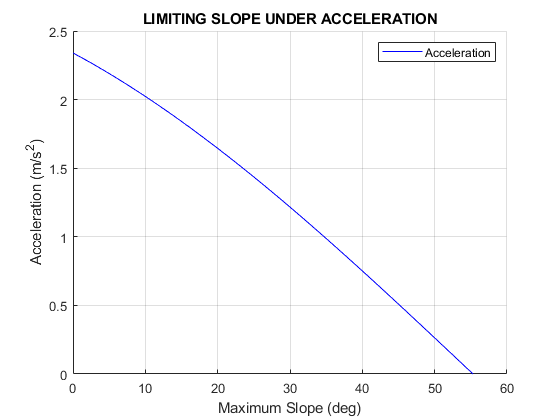

figure
hold on
plot(theta,dvdt_a,'blue')
hold off
xlabel('Maximum Slope (deg)')
ylabel("Acceleration (m/s^2)")
ylim([0 2.5])
grid on
title('LIMITING SLOPE UNDER ACCELERATION')
legend('Acceleration')

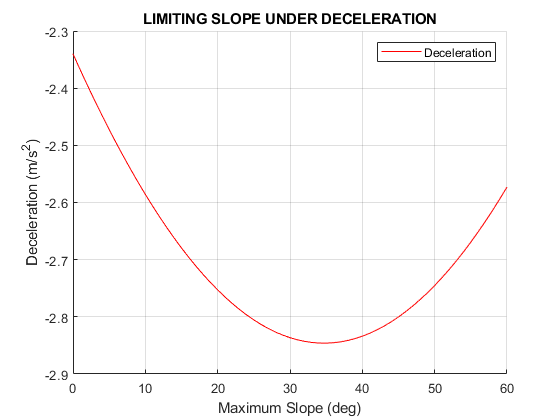

figure
hold on
plot(theta,dvdt_d,'red')
hold off
xlabel('Maximum Slope (deg)')
ylabel("Deceleration (m/s^2)")
legend('Deceleration')
grid on
title('LIMITING SLOPE UNDER DECELERATION')

### Impulsive Pitch-over Criteria


$$V_{limit} \leq \sqrt{2g(\sqrt{a^2+h^2} -h)}$$


v_limit = sqrt(2*g*(sqrt(a_^2+h_^2)-h_));
V_limit = [num2str(v_limit),'  m/s'];
disp(V_limit)

1.6416  m/s
